alpha = 1 + mod(235,3)

alpha = 2

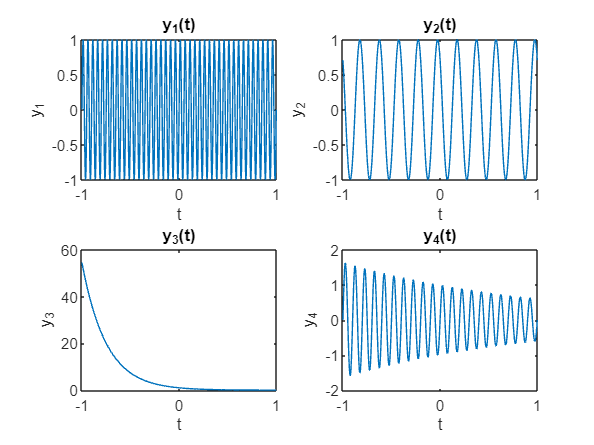

%question 1
t = linspace(-1,1,1000);
y1 = sin(20*pi*alpha*t);
subplot(2,2,1);
plot(t,y1)
xlabel('t');
ylabel('y_1');
title('y_1(t)');


y2= cos(5*pi*alpha*t + (pi/4));
subplot(2,2,2);
plot(t,y2);
xlabel('t');
ylabel('y_2');
title('y_2(t)');


y3 = exp(-2*alpha*t);
subplot(2,2,3);
plot(t,y3);
xlabel('t');
ylabel('y_3');
title('y_3(t)');



y4 = (exp(-0.25*alpha*t)).*(sin(20*pi*t));
subplot(2,2,4);
plot(t,y4);
xlabel('t');
ylabel('y_4');
title('y_4(t)');

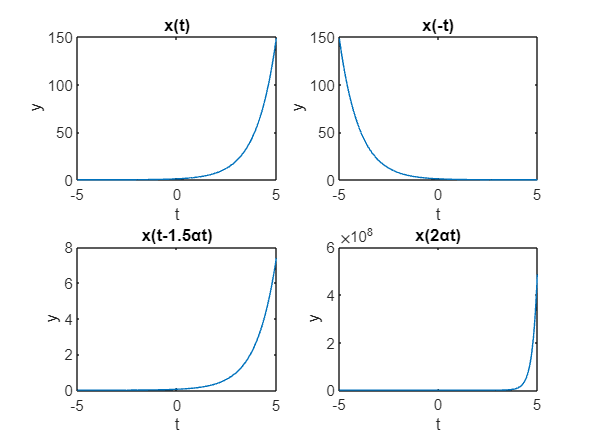

%question 2

t = linspace(-5,5,1000);
subplot(2,2,1);
plot(t,x(t));
title('x(t)')
xlabel('t');
ylabel('y');



subplot(2,2,2);
plot(t,x(-t));
title('x(-t)')
xlabel('t');
ylabel('y');



subplot(2,2,3);
plot(t,x(t-(1.5*alpha)))
title('x(t-1.5αt)')
xlabel('t');
ylabel('y');



subplot(2,2,4);
plot(t,x(2*alpha*t))
title('x(2αt)')
xlabel('t');
ylabel('y');

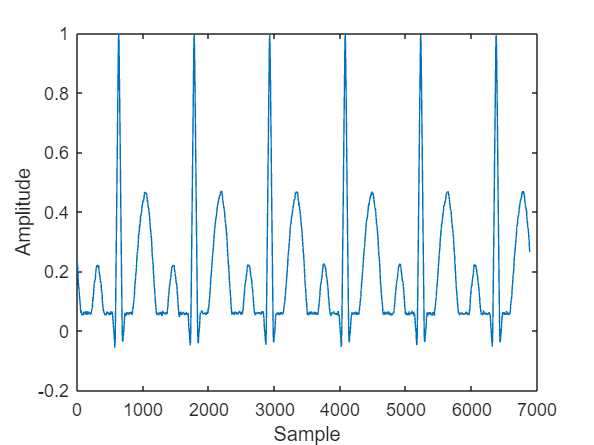

% question 3-1
ECG_Data = importdata('ECG_Data.txt');
subplot(1,1,1);
plot(ECG_Data);
xlabel('Sample');
ylabel('Amplitude')

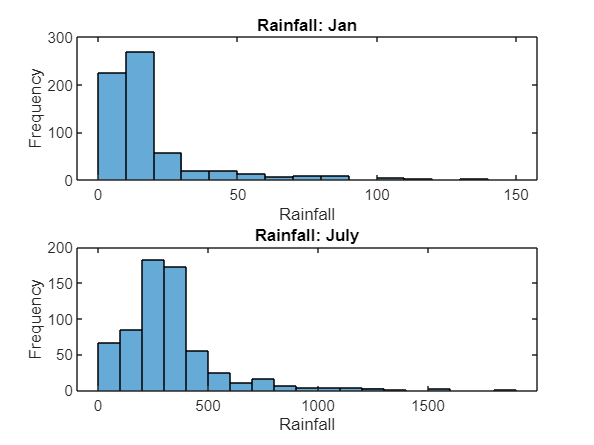

% question 3-2
RainFall_Jan = importdata('RainFallIndia_Jan.txt');
RainFall_July = importdata('RainFallIndia_July.txt');

subplot(2,1,1);
histogram(RainFall_Jan);
title('Rainfall: Jan')
xlabel('Rainfall')
ylabel('Frequency')

subplot(2,1,2);
histogram(RainFall_July);
title('Rainfall: July')
xlabel('Rainfall')
ylabel('Frequency')


disp('Mean rainfall - Jan');

Mean rainfall - Jan


mean(RainFall_Jan)

ans = 18.3513

disp('Mean rainfall - July');

Mean rainfall - July


mean(RainFall_July)

ans = 326.0936


disp('standard deviation - Jan');

standard deviation - Jan


std(RainFall_Jan)

ans = 21.0991

disp('standard deviation - July');

standard deviation - July


std(RainFall_July)

ans = 221.5326

% question 3-3
audio_data= importdata('track002.wav');
[y,Fs] = audioread('track002.wav'); 
%reads data from the file named filename, and returns sampled data, y, and a sample rate for that data, Fs.
sound(y,Fs);

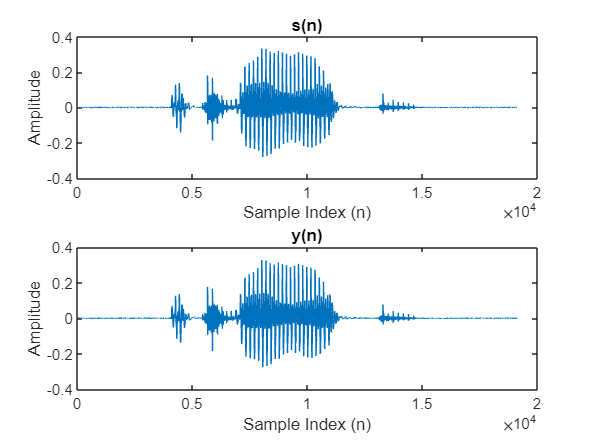

%question 4
[s,Fs] = audioread('speech.wav');
F =250*alpha;
y = s*cos(2*pi*(F/Fs)); 

subplot(2,1,1);
plot(s)
%sound(s,Fs)
title('s(n)')
xlabel('Sample Index (n)');
ylabel('Amplitude');

subplot(2,1,2);
plot(y)
title('y(n)')
sound(y,Fs)
xlabel('Sample Index (n)');
ylabel('Amplitude');


%question 5

t = linspace(1,10,2500);
fun1 = sin(2*pi*200*alpha*t);
fun2 = sin(2*pi*220*alpha*t);
fun3 = [fun1, fun2];
audiowrite('question5.wav',fun3,10000);
[aud_dat,sample_rate] = audioread('question5.wav');
sound(aud_dat,10000);


%question 6
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

duration = 1.0;             % Duration of each note in seconds
sample_rate = 44100;        % Number of samples per second (standard for audio)

sequence = [];

for freq = frequencies
    t = linspace(0, duration, duration * sample_rate);
    signal = sin(2 * pi * freq * t);
    sequence = [sequence, signal];
end

output_file = 'melody.wav';
audiowrite(output_file, sequence, sample_rate);
data = audioread('melody.wav');
sound(data,sample_rate);

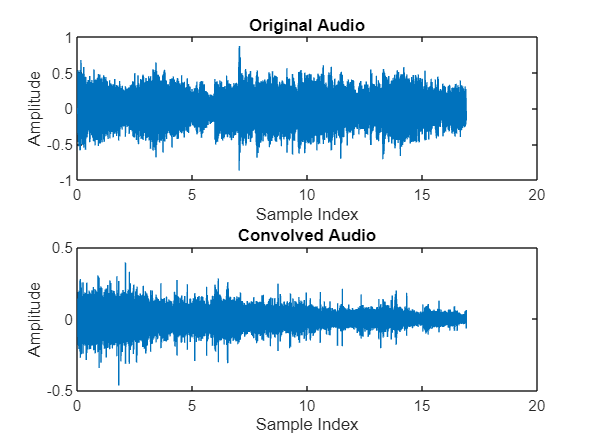

%question 7

audio_file = 'Track002.wav';
[audio, sample_rate] = audioread(audio_file);


conv_file = 'ConvFile2.txt';
conv_coeff = load(conv_file);

% Perform convolution
conv_result = conv(audio, conv_coeff);

% Normalize the result to prevent clipping
%conv_result = conv_result / max(abs(conv_result));

% Save the convolved audio as a .wav file
output_file = 'convolved_audio.wav';
audiowrite(output_file, conv_result, sample_rate);

% Plot the original audio and the convolved result (optional)
t = (0:length(audio)-1) / sample_rate;
t_conv = (0:length(conv_result)-1) / sample_rate;

subplot(2,1,1);
plot(t, audio);
title('Original Audio');
xlabel('Sample Index');
ylabel('Amplitude');

subplot(2,1,2);
plot(t_conv, conv_result);
title('Convolved Audio');
xlabel('Sample Index');
ylabel('Amplitude');



    
convolved_audio_file = 'convolved_audio.wav';
[convolved_audio, sample_rate] = audioread(convolved_audio_file);


sound(convolved_audio, sample_rate);

sound(audio,sample_rate);

function res = sine(F)
t = linspace(1,10,2500);
res = sine(2*pi*F.*t);
end
function y = x(t)
y = exp(t);
end